clear
clc
close all

syms Ki Kp Kd s
Psym = (2*(s+1))/(s^3+8*s^2+15*s)

$$Psym = \frac{2\,s+2}{s^{3}+8\,s^{2}+15\,s}$$

Propongo:

Gc1 = Ki/s;
Gc2 = Kp + Kd * s;
GYD_sym = simplify(Psym /(1+Psym*(Gc1+Gc2)))

$$GYD\_sym = \frac{2\,s+2}{\left(\frac{\left(2\,s+2\right)\,\left(\mathrm{Kp}+\mathrm{Kd}\,s+\frac{\mathrm{Ki}}{s}\right)}{s^{3}+8\,s^{2}+15\,s}+1\right)\,\left(s^{3}+8\,s^{2}+15\,s\right)}$$

GYR_sym = simplify(GYD_sym*Gc1)

$$GYR\_sym = \frac{\mathrm{Ki}\,\left(2\,s+2\right)}{s\,\left(\frac{\left(2\,s+2\right)\,\left(\mathrm{Kp}+\mathrm{Kd}\,s+\frac{\mathrm{Ki}}{s}\right)}{s^{3}+8\,s^{2}+15\,s}+1\right)\,\left(s^{3}+8\,s^{2}+15\,s\right)}$$

Encontrar los coeficientes

z = 0.5;
ts = 1;
w = 4/(z*ts);

[num, den] = numden(GYD_sym);
num = expand(num);

$$num = 2\,s^{2}+2\,s$$

coeffs_num = coeffs(num,s,'All');
den = expand(den);
coeffs_den = coeffs(den, s, 'All')

$$coeffs\_den = \left(\begin{array}{ccccc} 1 & 2\,\mathrm{Kd}+8 & 2\,\mathrm{Kd}+2\,\mathrm{Kp}+15 & 2\,\mathrm{Ki}+2\,\mathrm{Kp} & 2\,\mathrm{Ki} \end{array}\right)$$

coeffs_den_norm = simplify(coeffs_den/(coeffs_den(1)))

$$coeffs\_den\_norm = \left(\begin{array}{ccccc} 1 & 2\,\mathrm{Kd}+8 & 2\,\mathrm{Kd}+2\,\mathrm{Kp}+15 & 2\,\mathrm{Ki}+2\,\mathrm{Kp} & 2\,\mathrm{Ki} \end{array}\right)$$

poli_2do_orden1 = s^2 + 2*z*w*s + w^2;
poli_2do_orden2 = (s+10)*(s+8);
polinomio_deseado = poli_2do_orden1*poli_2do_orden2;
coeffs_deseado = coeffs(expand(polinomio_deseado), s, 'All')

$$coeffs\_deseado = \left(\begin{array}{ccccc} 1 & 26 & 288 & 1792 & 5120 \end{array}\right)$$

Resolución de sistema de ecuaciones

eqs = coeffs_den_norm(2:4) == coeffs_deseado(2:4)

$$eqs = \left(\begin{array}{ccc} 2\,\mathrm{Kd}+8=26 & 2\,\mathrm{Kd}+2\,\mathrm{Kp}+15=288 & 2\,\mathrm{Ki}+2\,\mathrm{Kp}=1792 \end{array}\right)$$

S = solve(eqs, [Ki, Kp, Kd]);
Ki = double(S.Ki(1))

Ki = 768.5000

Kp = double(S.Kp(1))

Kp = 127.5000

Kd = double(S.Kd(1))

Kd = 9

Numéricamente

P = tf([2 2], [1 8 15 0])

P =
 
       2 s + 2
  ------------------
  s^3 + 8 s^2 + 15 s
 
Continuous-time transfer function.




Gc1 = tf([0 Ki],[1 0])

Gc1 =
 
  768.5
  -----
    s
 
Continuous-time transfer function.



Gc2 = tf([Kd Kp],1)

Gc2 =
 
  9 s + 127.5
 
Continuous-time transfer function.



GYD = feedback(P,(Gc1+Gc2))

GYD =
 
               2 s^2 + 2 s
  --------------------------------------
  s^4 + 26 s^3 + 288 s^2 + 1792 s + 1537
 
Continuous-time transfer function.



GYR = GYD * Gc1

GYR =
 
              1537 s^2 + 1537 s
  ------------------------------------------
  s^5 + 26 s^4 + 288 s^3 + 1792 s^2 + 1537 s
 
Continuous-time transfer function.



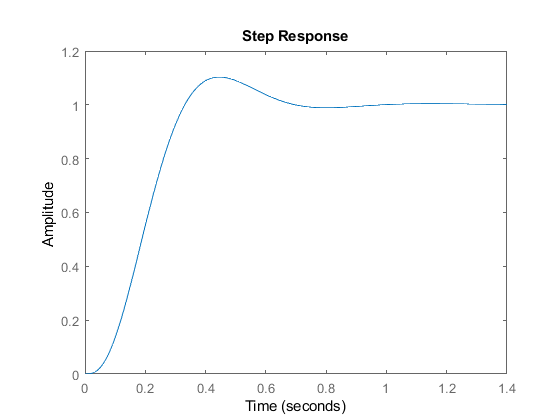

step(GYR)

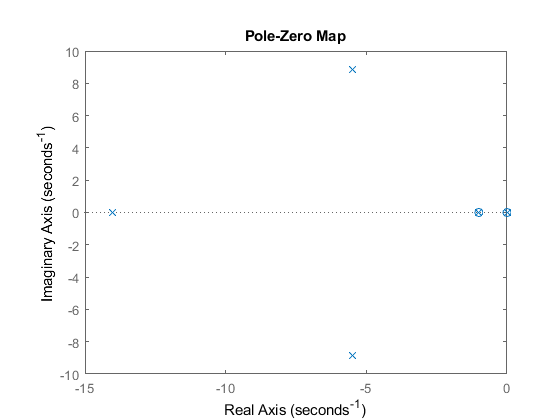

pzmap(GYR)

stepinfo(GYR)

ans = struct with fields:
        RiseTime: 0.2026
    SettlingTime: 0.6375
     SettlingMin: 0.9146
     SettlingMax: 1.1032
       Overshoot: 10.3205
      Undershoot: 0
            Peak: 1.1032
        PeakTime: 0.4469


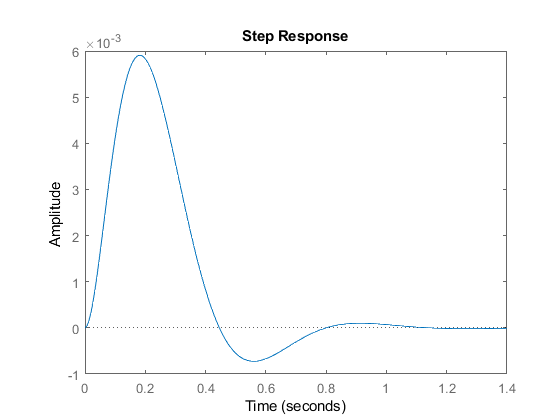

step(GYD)

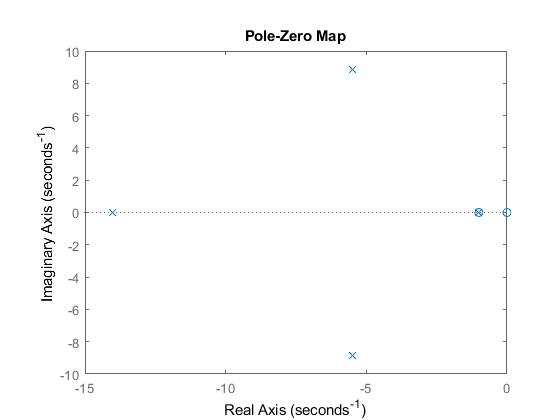

pzmap(GYD)

stepinfo(GYD)

ans = struct with fields:
        RiseTime: 0
    SettlingTime: 0.7533
     SettlingMin: -7.2405e-04
     SettlingMax: 0.0059
       Overshoot: Inf
      Undershoot: Inf
            Peak: 0.0059
        PeakTime: 0.1840


vt = 0:0.01:2

vt =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


u = vt

u =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


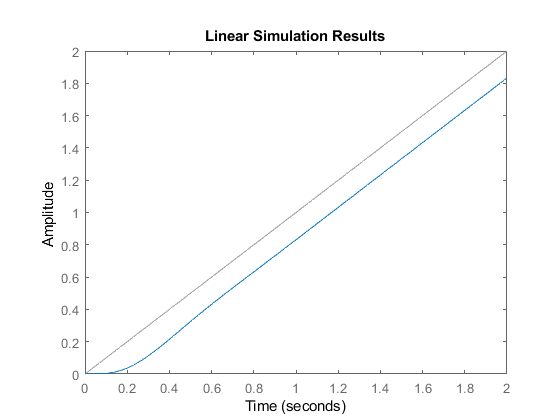

lsim(GYR,u,vt)

u = vt.^2

u =          0    0.0001    0.0004    0.0009    0.0016    0.0025    0.0036    0.0049    0.0064    0.0081    0.0100    0.0121    0.0144    0.0169    0.0196    0.0225    0.0256    0.0289    0.0324    0.0361    0.0400    0.0441    0.0484    0.0529    0.0576    0.0625    0.0676    0.0729    0.0784    0.0841    0.0900    0.0961    0.1024    0.1089    0.1156    0.1225    0.1296    0.1369    0.1444    0.1521    0.1600    0.1681    0.1764    0.1849    0.1936    0.2025    0.2116    0.2209    0.2304    0.2401


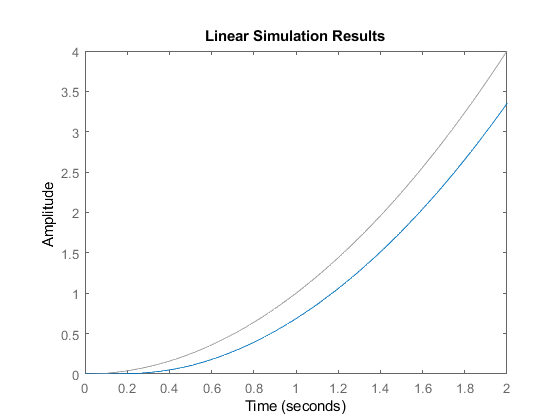

lsim(GYR,u,vt)